## nirs.modules.default_modules.FIR_model

This module runs a default modules to get group level statistical analysis. 

The following modules are included in this default: nirs.modules.RemoveStimLess, nirs.modules.FixNaNs, nirs.modules.Resample, nirs.modules.OpticalDensity, nirs.modules.TrimBaseLine, nirs.modules.AR_IRLS, and nirs.modules.MixedEffects.

**Example Usage: **

for i = 1:10
    raw(i) = nirs.testing.simData([], @(t)nirs.testing.blockedStimDesign(t,15,25,2));
    % task-based 15s duration, 25s between onset, and 2 conditions
end

job = nirs.modules.default_modules.FIR_model();
GroupStats = job.run(raw);

Import data module skipped: Data provided
Hb created in workspace
............................Finished    1 of   10.
............................Finished    2 of   10.
............................Finished    3 of   10.
............................Finished    4 of   10.
............................Finished    5 of   10.
............................Finished    6 of   10.
............................Finished    7 of   10.
............................Finished    8 of   10.
............................Finished    9 of   10.
............................Finished   10 of   10.
SubjStats created in workspace
GroupStats created in workspace


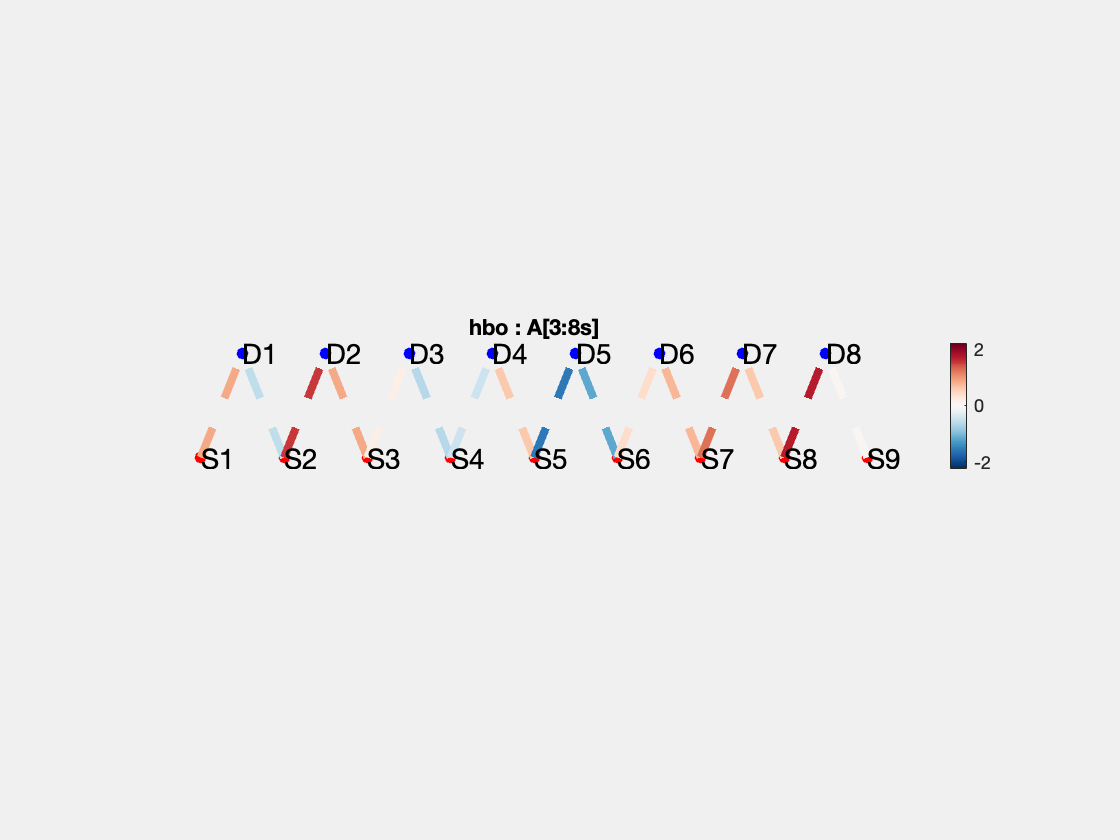

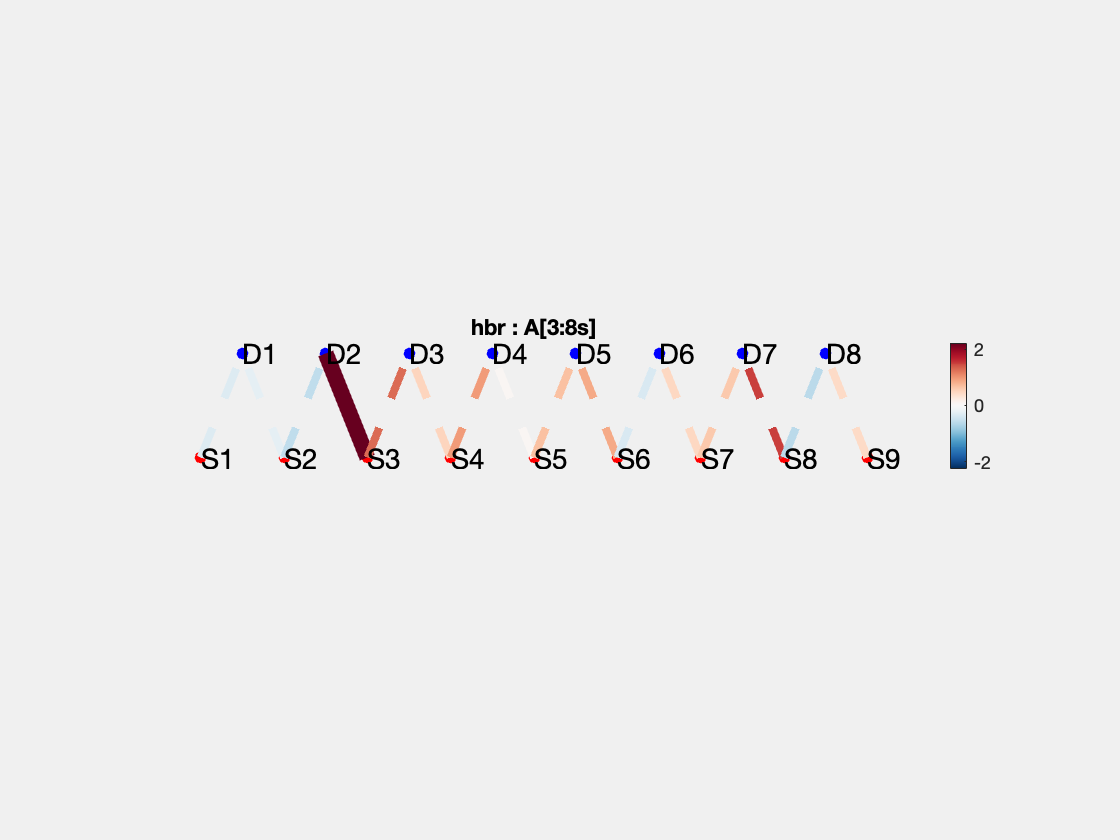

ans =   1×2 Figure array:

    Figure    Figure



% a contrast window based on time  
GroupStats.ttest({'A[3:8s]'}).draw('tstat',[],'p<0.05')

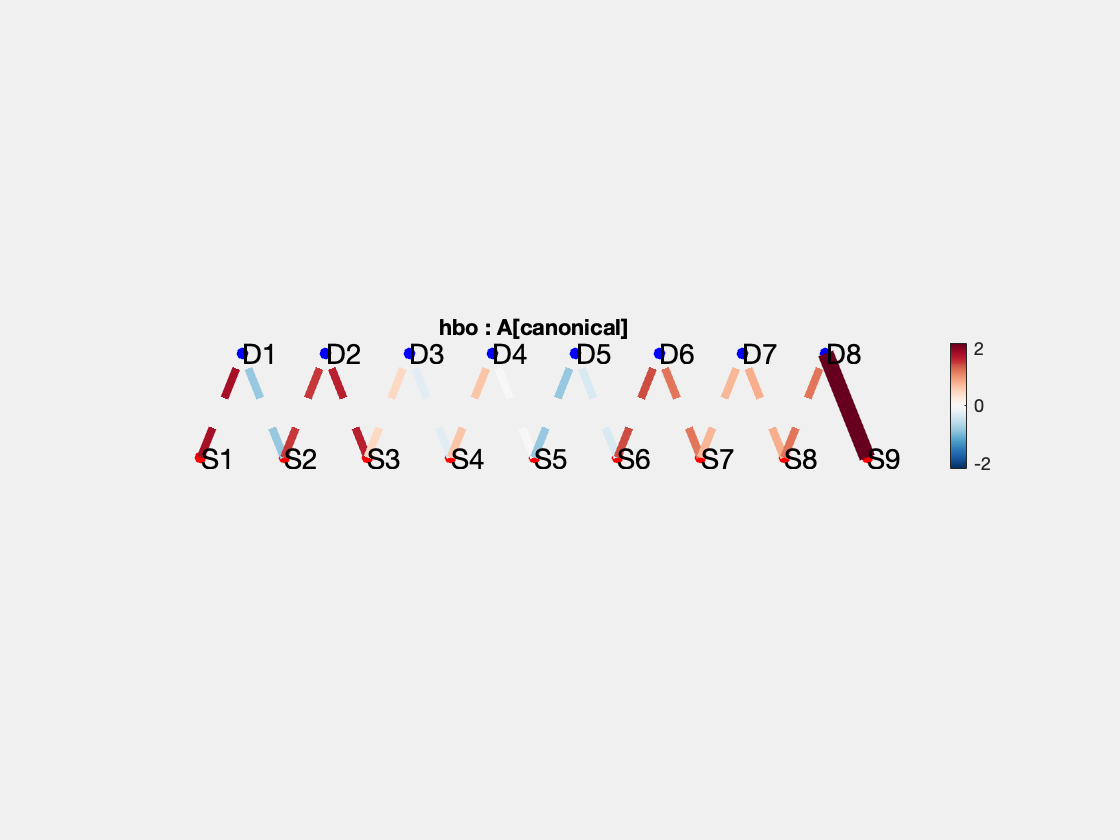


% a contrast window using a tapered shape (based on the canonical model)
GroupStats.ttest({'A[canonical]'}).draw('tstat',[],'p<0.05',[],[],'hbo');

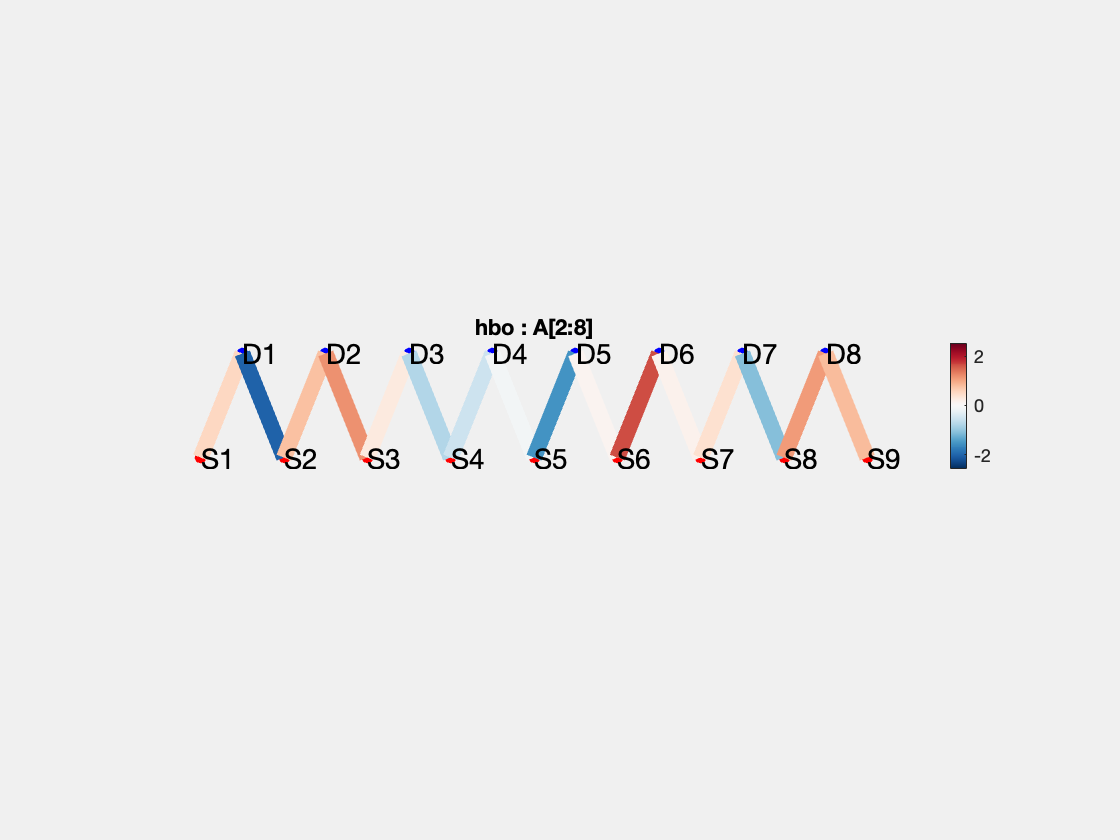

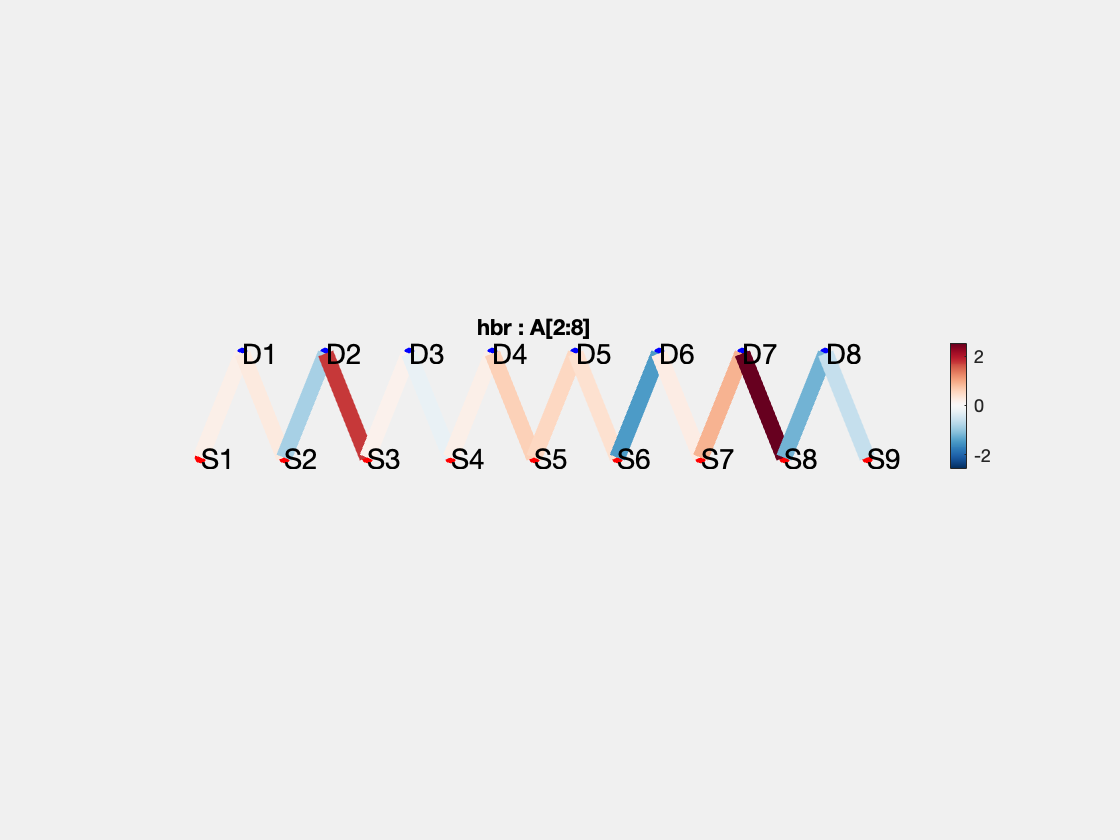

ans =   1×2 Figure array:

    Figure    Figure



% a contast window based on the sample point (2-8 is the 2nd through 8th
% beta term and requires knowledge of the FIR binwidth).  
GroupStats.ttest({'A[2:8]'}).draw 